Fig 1B

x = csvread('GSR in sec session 33.csv',2,1);
size(x)

ans =         3024           2


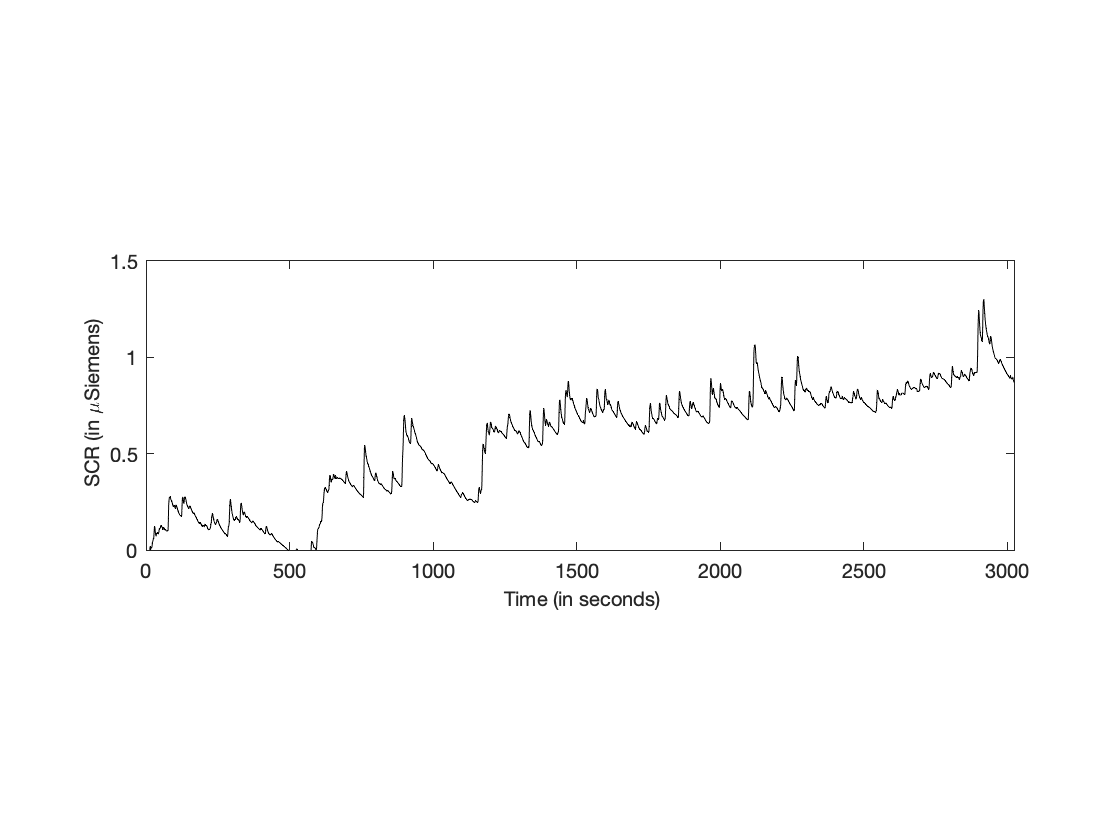

plot(x(:,1),x(:,2),'-k')
pbaspect([3 1 1])
axis([0 max(x(:,1)) 0 1.5])
xlabel('\fontsize{10} Time (in seconds)')
ylabel('\fontsize{10} SCR (in \muSiemens)')

Fig 1C

x = csvread('Session 3 P3.csv',2,1);
size(x)

ans =         3015           2


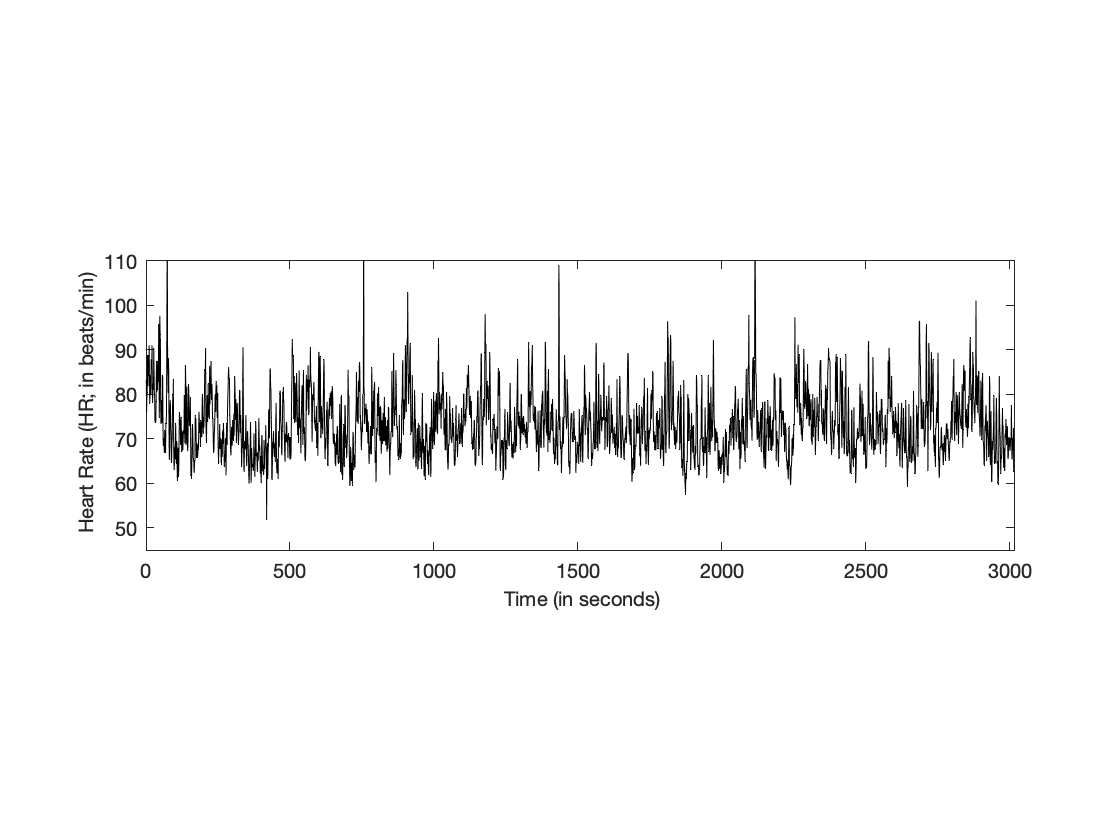

plot(x(:,2),x(:,1),'-k')
pbaspect([3 1 1])
axis([0 max(x(:,2)) 45 110])
xlabel('\fontsize{10} Time (in seconds)')
ylabel('\fontsize{10} Heart Rate (HR; in beats/min)')

Fig 2A

pick_sessions = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 21, 22, 23, 24];
legend_sessions = {};
figure;
hold on;
timeSecs_agg = [];
mispricing_agg = [];
for i = 1:length(pick_sessions)
    s = pick_sessions(i);
    s_name = ['saveit_official ' num2str(s) ' v2.csv'];
    dtable = readtable(s_name);
    stable = table2struct(dtable,'ToScalar',true);
    mispricing = stable.mispricing;
    timeSecs = stable.timeSecs;
    timeSecs_agg = [timeSecs;timeSecs_agg];
    mispricing_agg = [mispricing;mispricing_agg];
    plot(timeSecs,mispricing,'.')
    pbaspect([2 1 1])
    xlabel('\fontsize{14} Time (in seconds)')
    ylabel('\fontsize{14} Trade price minus fundamental value')
    axis([0 3100 -700 600])
    legend_sessions{i} = string(strcat('SesID',{' '},num2str(s)));
    lgd = legend(legend_sessions,'Location',"southoutside",'Orientation',"horizontal");
    lgd.NumColumns = 6;
end

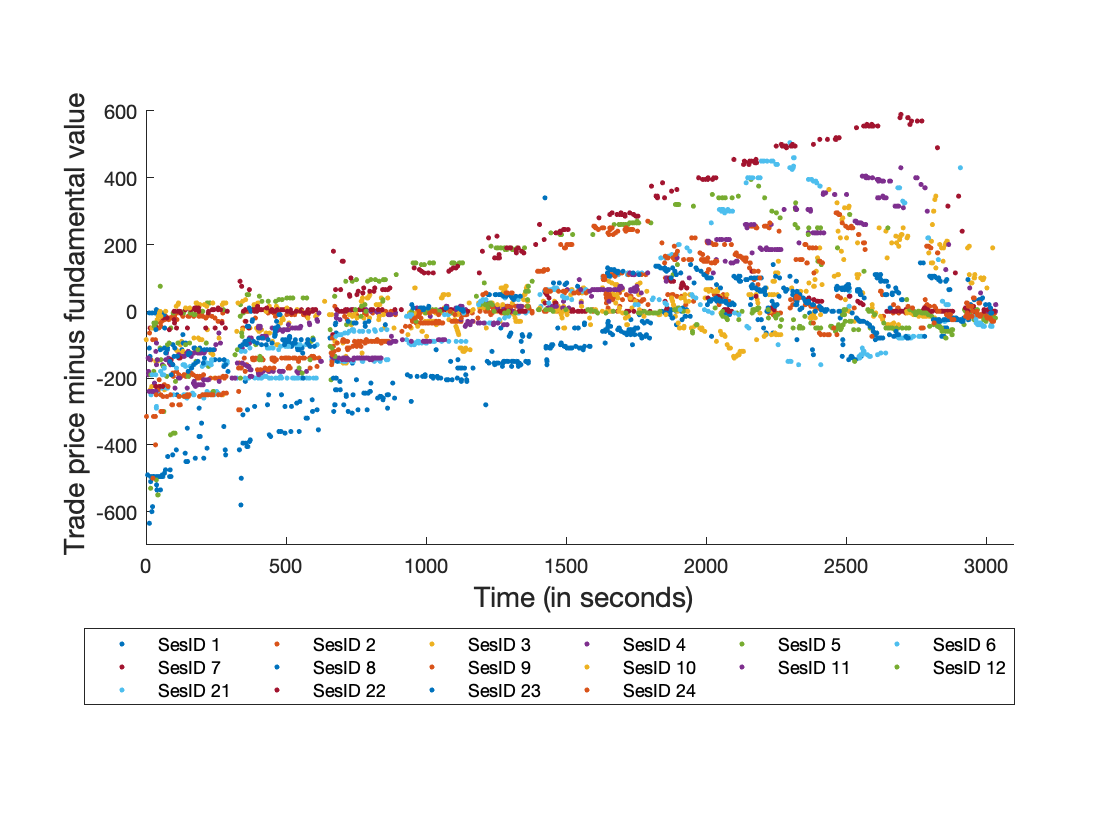

hold off;

Fig 2B

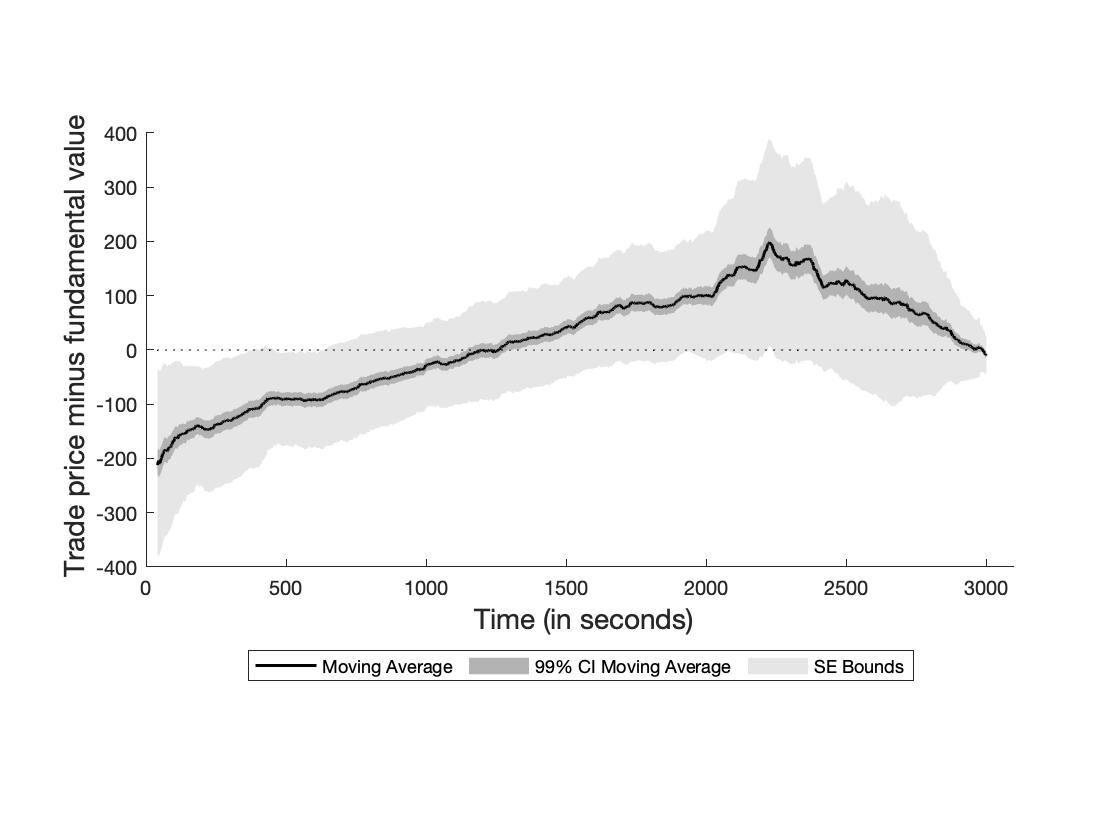

figure;
timeSecs_agg = timeSecs_agg(~isnan(mispricing_agg));
mispricing_agg = mispricing_agg(~isnan(mispricing_agg));
tm_sort = sortrows([timeSecs_agg,mispricing_agg], 1);
x_sort = movmean(tm_sort(:,1),320);
mean_sort = movmean(tm_sort(:,2),320);
std_sort1 = (movstd(tm_sort(:,2),320)/sqrt(320))* 2.576;
std_sort2 = movstd(tm_sort(:,2),320);
upper = mean_sort+std_sort1;
lower = mean_sort-std_sort1;
upper2 = mean_sort+std_sort2;
lower2 = mean_sort-std_sort2;
l3 = fill([x_sort; x_sort(end:-1:1)],[lower2; upper2(end:-1:1)],[0.9, 0.9, 0.9],'LineStyle','none');
hold on;
l2 = fill([x_sort; x_sort(end:-1:1)],[lower; upper(end:-1:1)],[0.7, 0.7, 0.7],'LineStyle','none');
l1 = plot(x_sort,mean_sort,'-k','LineWidth',1.5);
plot(x_sort,zeros(length(x_sort)),':k')
pbaspect([2 1 1])
xlabel('\fontsize{14} Time (in seconds)')
ylabel('\fontsize{14} Trade price minus fundamental value')
axis([0 3100 -400 400])
set(gca,'box','off')
legend([l1,l2,l3],{'Moving Average','99% CI Moving Average','SE Bounds'},'Location',"southoutside",'Orientation',"horizontal");

Fig 3

pick_sessions = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 21, 22, 23, 24];
tick_sessions = {};
figure;
hold on;
earnings_agg = [];
for i = 1:length(pick_sessions)
    s = pick_sessions(i);
    s_name = ['save_earnings' num2str(s) '.csv'];
    dtable = readtable(s_name);
    stable = table2struct(dtable,'ToScalar',true)
    earnings = stable.earning./1000;
    earnings_agg = [earnings_agg;earnings];
    xvariable = i.*ones(length(earnings),1);
    if sum(s == [1, 2, 3, 8, 9, 11, 21, 22, 23, 24]) > 0
        simbool = 'ok'
    else 
        simbool = 'xk'
    end
    if s==1 || s==4
        plot(xvariable,earnings,simbool)
    else
        plot(xvariable,earnings,simbool,'HandleVisibility','off')
    end
    pbaspect([2 1 1])
    axis([0.5 length(pick_sessions)+0.5 5 40]);
    xlabel('\fontsize{14} Session ID')
    ylabel('\fontsize{14} Earnings in AUD')
    xticks(1:1:16)
    tick_sessions{i} = num2str(s);
    xticklabels(tick_sessions)
end

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'xk'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'xk'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'xk'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'xk'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'xk'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'xk'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

stable = struct with fields:
         Var1: [8×1 double]
    Unnamed_0: [8×1 double]
           ID: {8×1 cell}
       volume: [8×1 double]
      earning: [8×1 double]
      holding: [8×1 double]
      session: [8×1 double]


simbool = 'ok'

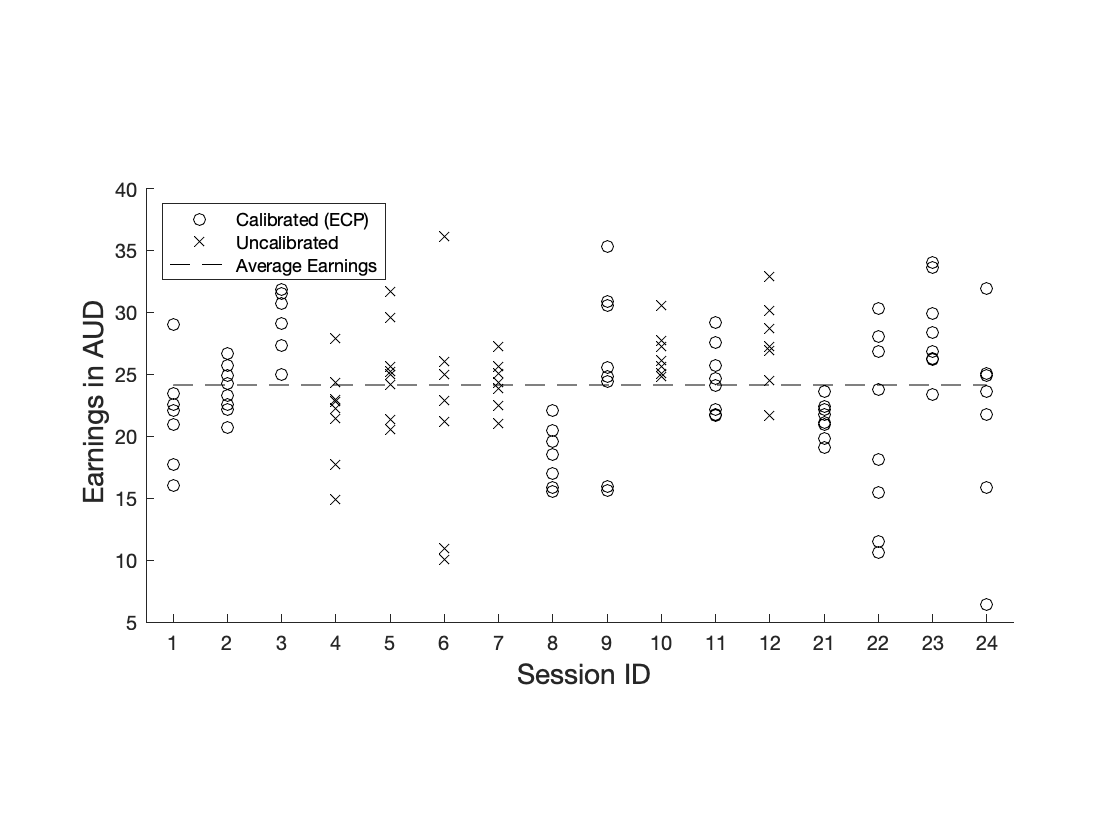

plot(1:1:16,ones(1,16)*mean(earnings_agg),'--k')
legend({'Calibrated (ECP)','Uncalibrated','Average Earnings'},'Location',"northwest",'Orientation',"vertical")
hold off;

Fig 5A

x = csvread('HeartrateBASpread_s3_p3.csv',1,1);
size(x)

ans =    473     3


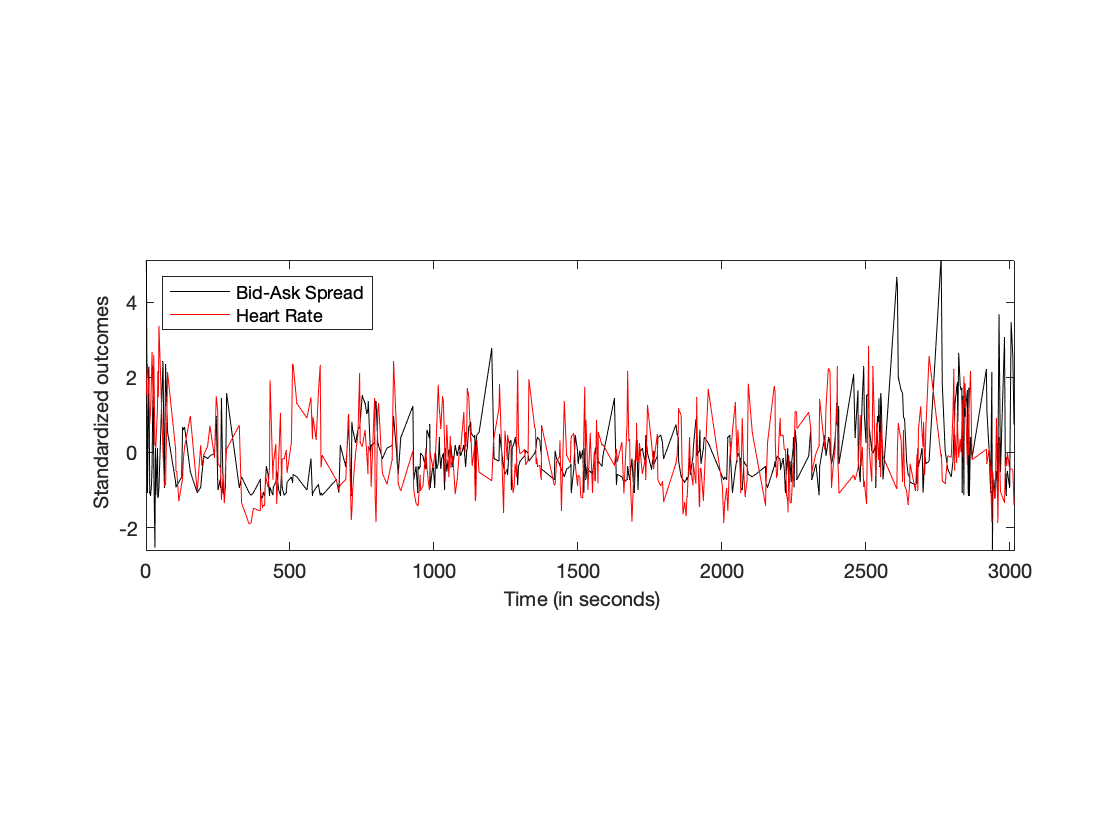

plot(x(:,1),x(:,2),'-k')
hold on;
pbaspect([3 1 1])
axis([0 max(x(:,1)) -2.6 5.1])
xlabel('\fontsize{10} Time (in seconds)')
ylabel('\fontsize{10} Standardized outcomes')
plot(x(:,1),x(:,3),'-r')
legend('Bid-Ask Spread','Heart Rate','Location','northwest')
hold off;

Fig 5B

x = csvread('HeartrateBASpread_s3_p3.csv',1,1);
size(x)

ans =    473     3


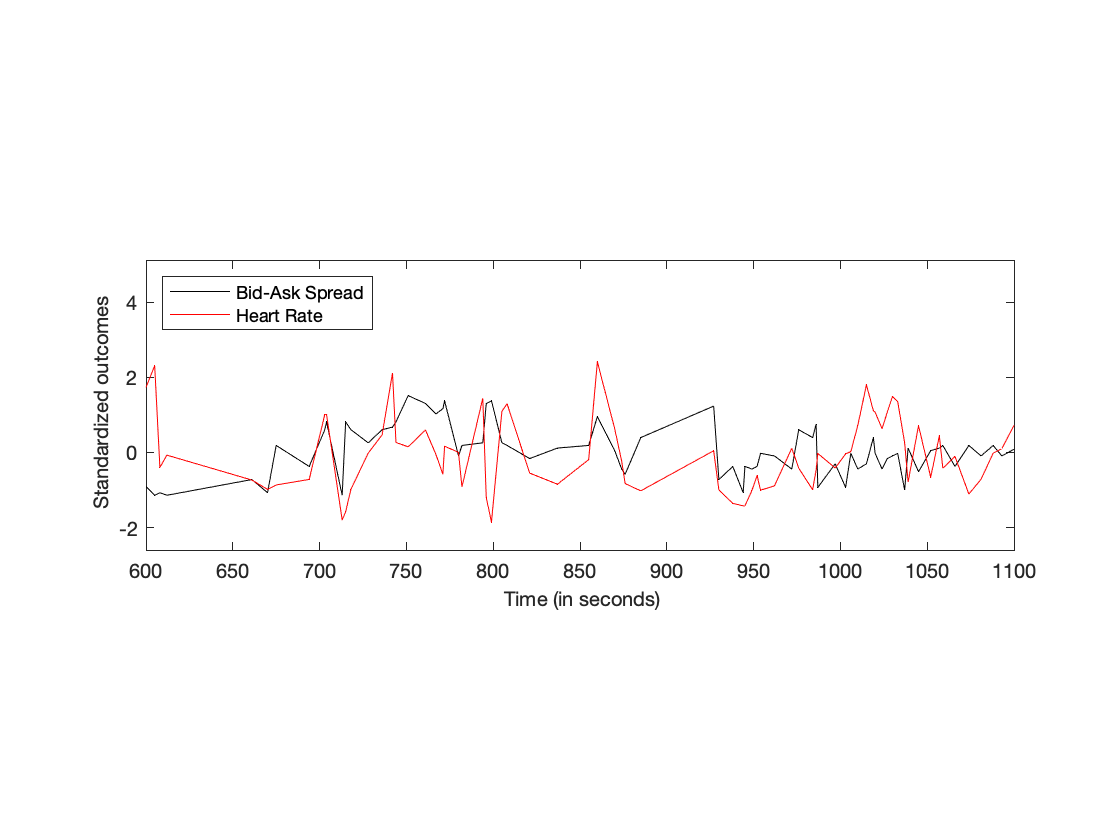

plot(x(:,1),x(:,2),'-k')
hold on;
pbaspect([3 1 1])
axis([600 1100 -2.6 5.1])
xlabel('\fontsize{10} Time (in seconds)')
ylabel('\fontsize{10} Standardized outcomes')
plot(x(:,1),x(:,3),'-r')
legend('Bid-Ask Spread','Heart Rate','Location','northwest')
hold off;

FIG 5C

x = csvread('HeartrateBASpread_s3_p3.csv',1,1);
size(x)

ans =    473     3


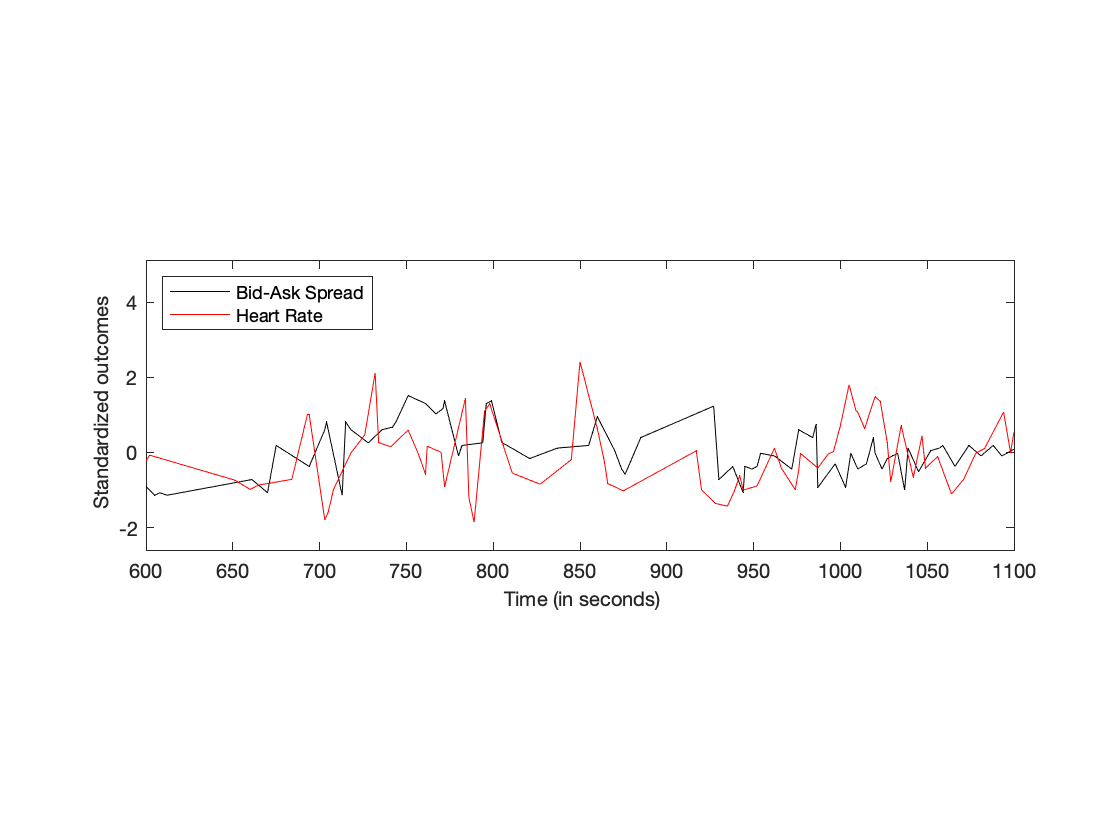

plot(x(:,1),x(:,2),'-k')
hold on;
pbaspect([3 1 1])
axis([600 1100 -2.6 5.1])
xlabel('\fontsize{10} Time (in seconds)')
ylabel('\fontsize{10} Standardized outcomes')
plot(x(:,1)-10,x(:,3),'-r')
legend('Bid-Ask Spread','Heart Rate','Location','northwest')
hold off;

Fig 5D

x = csvread('HeartrateMisPricing_s8_p7.csv',1,1);
size(x)

ans =    160     3


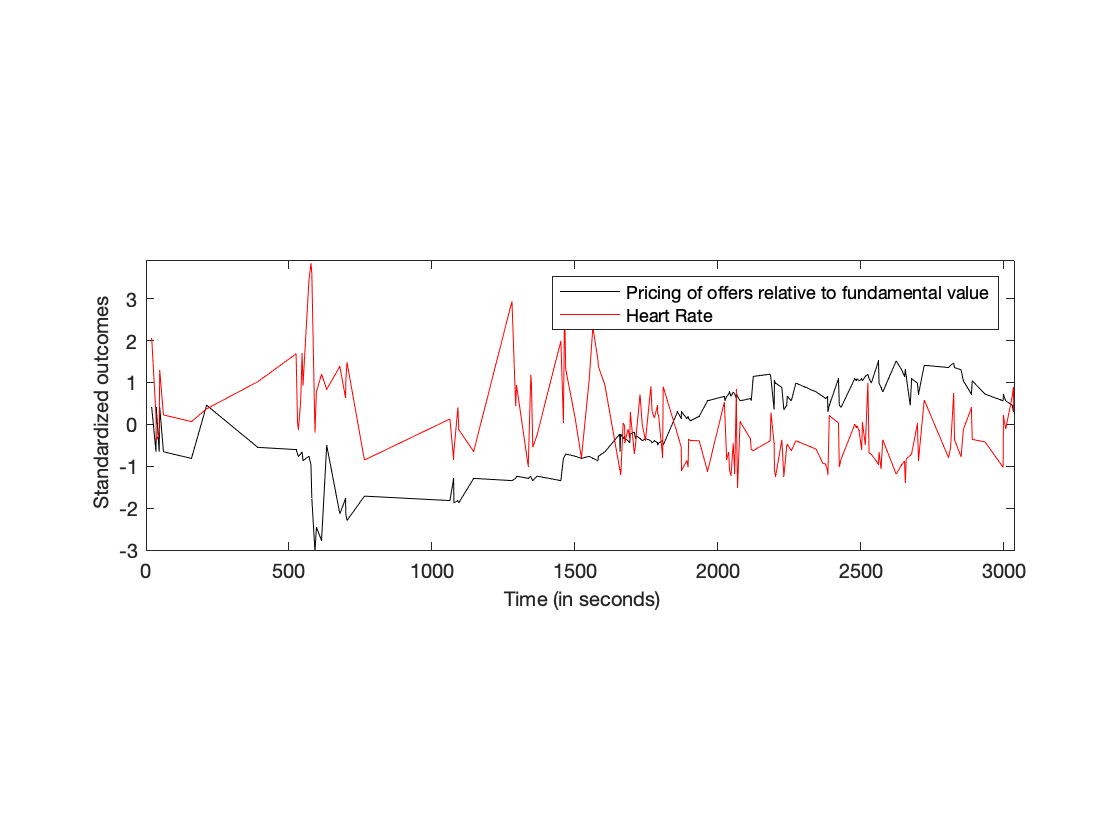

plot(x(:,1),x(:,2),'-k')
hold on;
pbaspect([3 1 1])
axis([0 max(x(:,1)) -3 3.9])
xlabel('\fontsize{10} Time (in seconds)')
ylabel('\fontsize{10} Standardized outcomes')
plot(x(:,1),x(:,3),'-r')
legend('Pricing of offers relative to fundamental value','Heart Rate')
hold off;